L5 Segona Part                                                                                       Marta Granero I Martí

## Exercici 3

Problema: Calcular aproximacions del nombre 𝜋  fent ús de la fórmula

                                    
$$\displaystyle\pi=\displaystyle \int _{0}^{1}\frac {4}{1+t^2}\,dt\,.\qquad\qquad (1)$$


a) Useu la regla composta de Trapezis, preneu  $h=\displaystyle\frac{1}{2k},\ k=4,16,\,64$ És l'error proporcional a $h^p$ Per què? Presenteu els resultats en taules.

clear vars
format longG

%funció
f = @(t) 4./(1 + t.^2);

%interval integració
a = 0;
b = 1;

%aplicació mètode
h = [1./(2.*([4 16 64]))]';
for k = 0:2
    trapezis(k+1).h = h(k+1);
    trapezis(k+1).valor = trap(f,a,b,h(k+1));
    trapezis(k+1).ErrorAbsolut = abs(trapezis(k+1).valor-pi);
    trapezis(k+1).ErrorRelatiu = trapezis(k+1).ErrorAbsolut/sqrt(2);
    trapezis(k+1).DecimalsCorrectes = abs(fix(-log10(2*trapezis(k+1).ErrorAbsolut)));
    trapezis(k+1).XifresSignificatives = abs(fix(-log10(2*trapezis(k+1).ErrorRelatiu)));
end

%fem servir l'estructura de dades (trapezis) i ens n'aprofitem per printar la
%taula de valors
trapezis

trapezis = 1×3 struct array with fields:
    h
    valor
    ErrorAbsolut
    ErrorRelatiu
    DecimalsCorrectes
    XifresSignificatives


Sí, l'error és proporcional a $h^p$. Podem observar que l'error és proporcional a la mida de l'interval, o a la granularitat que se'ns dóna amb h. Per tant, a mesura que la mida de l'interval decreix en un factor de p, el valor de l'error absolut decreix en la mateixa proporció aproximadament. Concretament l'error és proporcional a la derivada segona d'aquesta funció, que és: $\frac{8\left(3x^2-1\right)}{\left(x^2+1\right)^3}$

b) Useu la regla composta de Simpson, preneu  $h=\displaystyle\frac{1}{2k},\ k=4,16,\,64$ És l'error proporcional a $h^p$ Per què? Presenteu els resultats en taules.

clear vars

%funció
f = @(t) 4./(1 + t.^2);

%interval integració
a = 0;
b = 1;

%aplicació mètode
h = [1./(2.*([4 16 64]))]';
for k = 0:2
    simpson(k+1).h = h(k+1);
    simpson(k+1).valor = simp(f,a,b,h(k+1));
    simpson(k+1).ErrorAbsolut = abs(simpson(k+1).valor-pi);
    simpson(k+1).ErrorRelatiu = simpson(k+1).ErrorAbsolut/sqrt(2);
    simpson(k+1).DecimalsCorrectes    = fix(-log10(2*simpson(k+1).ErrorAbsolut));
    simpson(k+1).XifresSignificatives = fix(-log10(2*simpson(k+1).ErrorRelatiu)); 
end

simpson

simpson = 1×3 struct array with fields:
    h
    valor
    ErrorAbsolut
    ErrorRelatiu
    DecimalsCorrectes
    XifresSignificatives


Conclusió anàloga a l'apartat anterior, però amb l'error proporcial a la derivada 4 d'aquesta funció i proporcional a: $\frac{96\left(5x^4-10x^2+1\right)}{\left(x^2+1\right)^5}$

c) Apliqueu el métode de Romberg, comenceu amb $h=\displaystyle\frac{1}{2^n},\ n=0,1,2,3,4,\dots$per millorar l’aproximació de 𝜋 obtinguda en els apartats anteriors fins obtenir 14 xifres decimals correctes. Presenteu els resultats en taules.

clear vars

%funció
f = @(t) 4./(1 + t.^2);

%interval integració
a = 0;
b = 1;

%R(N,N) és la millor aproximació feta fins al moment
%millor aproximació de totes -> R(8,8) aproximació correcta amb 14 xifres decimals correctes
[R] = rombergM(f,a,b,8,eps);

%R(7,7), R(8,8), R(9,9)

h = [1./(2.^(0:20))];
for k=0:8
      romberg(k+1).h = h(k+1);
      ans = rombergM(f,a,b,romberg(k+1).h,eps);
      romberg(k+1).valor = ans(k+1,k+1);
      romberg(k+1).ErrorAbsolut = abs(romberg(k+1).valor-pi);
      romberg(k+1).ErrorRelatiu = romberg(k+1).ErrorAbsolut/sqrt(2);
      romberg(k+1).DecimalsCorrectes    = fix(-log10(2*romberg(k+1).ErrorAbsolut));
      romberg(k+1).XifresSignificatives = fix(-log10(2*romberg(k+1).ErrorRelatiu)); 
end

romberg

romberg = 1×9 struct array with fields:
    h
    valor
    ErrorAbsolut
    ErrorRelatiu
    DecimalsCorrectes
    XifresSignificatives


d) Useu una tècnica de simulació (Mètode de MonteCarlo) per a determinar 𝜋 preneu mostres de mida $10^m$, 𝑚≥ 3,4,5,6,…10m. Presenteu els resultats que s’obtenen en taules.

clear all
format longG

f = @(x) 4./(1 + x.^2);
a = 0; b = 1;
for i=3:8
    M = 10^i;
    x = a+ (b-a)*rand(M,1);
    y = (a+ (b-a)*rand(M,1))*4;
    iter = 0;
    for j = 1:M
        if y(j) <= f(x(j))
            iter = iter+1;
        end
    end
    iter;
    area = ((b-a)^2*iter/M)*4;

    dsM(i-2).i     = i;
    dsM(i-2).M     = M;
    dsM(i-2).area  = area;
    dsM(i-2).ordre = 1/sqrt(M);
    dsM(i-2).ErrorAbsolut    = abs(dsM(i-2).area-pi);
    dsM(i-2).ErrorRelatiu    = dsM(i-2).ErrorAbsolut/sqrt(2);
    dsM(i-2).DecimalsCorrectes       = fix(-log10(2*dsM(i-2).ErrorAbsolut));
    dsM(i-2).XifresSignificatives    = fix(-log10(2*dsM(i-2).ErrorRelatiu));
end

dsM

dsM = 1×6 struct array with fields:
    i
    M
    area
    ordre
    ErrorAbsolut
    ErrorRelatiu
    DecimalsCorrectes
    XifresSignificatives


e) Useu 𝜋 de Matlab®, calculeu l’error absolut i l’error relatiu de les aproximació dels apartats (a), (b), (c) i (d). Quantes xifres significatives correctes s’han obtingut? Explica els teus càlculs.  Com s’ha de pendre la mostra de gran en el mètode de MonteCarlo per obtenir la mateixa exactitud que amb la fórmula dels trapezis? Podem obtenir la mateixa exactitud que amb la fórmula de Simpson? Argumenta la teva resposta

Per cada apartat he calculat el nombre de xifres significatives i es poden veure respectivament a les taules d'aquests. Per calcular-les he emprat l'error absolut entre el valor aproximat de pi i pi, amb això he pogut trobar l'error relatiu, que m'ha permès aplicant logaritmes, obtenir les xifres significatives.

Amb una k=64 pel mètode trapezis, he obtngut 4 xifres significatives correctes, i amb el mètode de Montecarlo per aconseguir-ho, he necessitat una mostra de 10^8 per a l'execució realitzada un cop executada la secció. Cal tenir en compte però, que no sempre amb una mostra de 10^8 obtindrem 4 xifres significatives, ja que tenim la component random alhora de generar els valors pseudoalteroris(x,y) i per tant, per cada execució i per cada mostra M^i, sent i:3,..8, obtindrem amb una mostra M^i un nombre de xifres significatives diferents.

Execució diferent: on per una mostra de 10^8 s'ha obtingut un nombre de xifres significatives que les que hem obtingut per aquesta execuió.

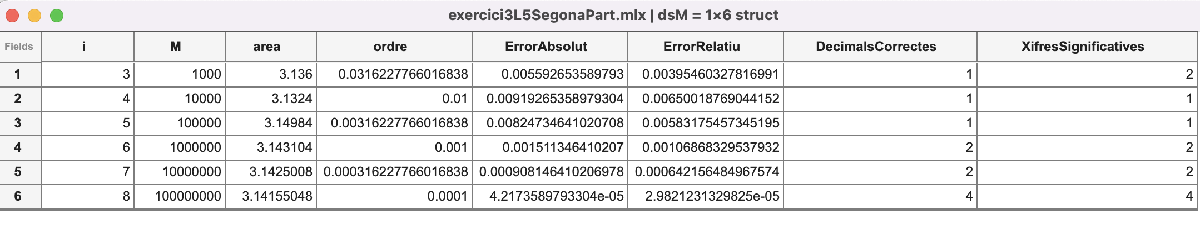

I responent a la pregunta sobre si podríem obtenir la mateixa exactitud que el mètode de simpson, la resposta és negativa, ja que amb simpson, per a l'execució realitzada, tenim una precisió que MATLAB cataloga d'infinita, ja que no sap diferenciar entre el valor aproximat i pi, i per tant assolint un nombre xifres signifiatives infinites. Amb el mètode de Montecarlo seria possible equiparar aquest resultat però amb una mostra molt superior a 10^8. Malauradament no ho puc provar de forma empírica, ja que cada vegada que intento fer-ho per un valor més gran a 8, i per tant amb mostres de l'ordre (10^9,10^10), MATLAB es tanca. Tot i així, tambñe caldria tenir en compte la variabilitat de la mostra que aconseguira obtenir un nombre de xifres significatives que fossin infinites, degut a la generació pseudoaleatòria amb la que comptem.

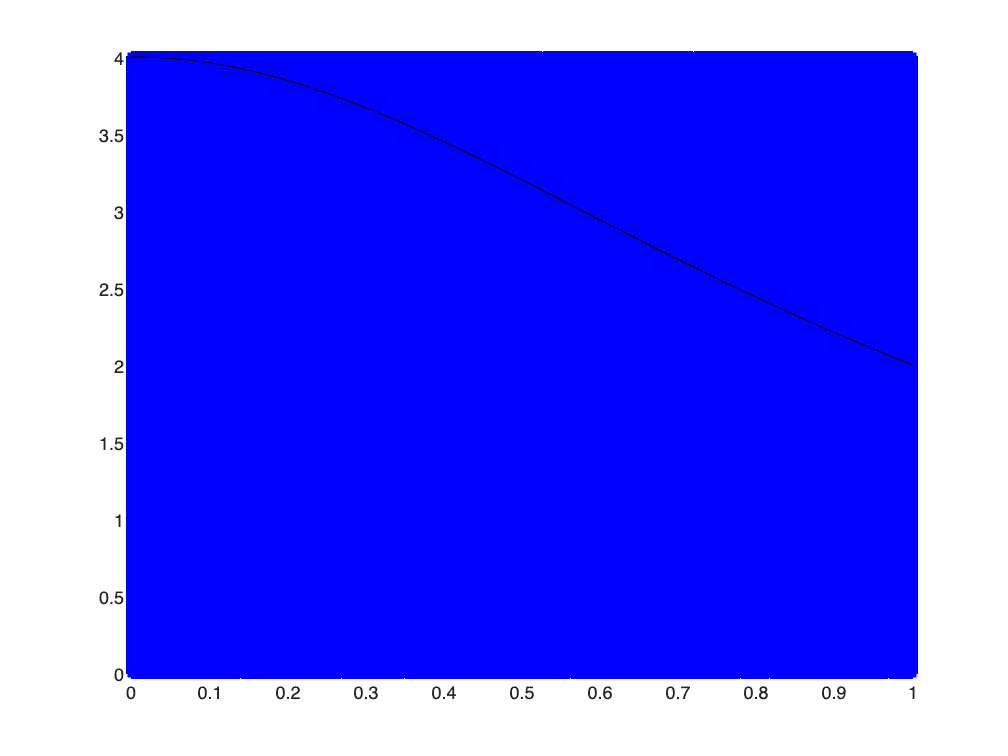

%Visualització del problema per a k=7
f = @(x) 4./(1 + x.^2);
a = 0; b = 1;
for i=3:7
    M = 10^i;
    x = a + (b-a)*rand(M,1);
    y = (a+ (b-a)*rand(M,1))*4;
    hold on
    plot(x,y,'b*')
    fplot(f, [a,b],'black')
    hold off
    grid
    iter = 0;
    for j = 1:M
        if y(j) <= f(x(j))
            iter = iter+1;
        end
    end
    iter;
    area = ((b-a)^2*iter/M)*4;
end

function r = trap(f,a,b,granularitat)
%Implementació escollida per implementar l'apartat de trapezis
suma = 0;
it   = a+granularitat;
while it < b
    suma = suma + f(it);
    it   = it + granularitat;
end
r = granularitat/2 * (f(a) + 2*suma + f(b));
end


%Implementació escollida per implementar l'apartat de simpson
function r = simp(f,a,b,granularitat)
x   = a:granularitat:b;
r   = 0;
n   = length(x);
mid = (x(1:n-1) + x(2:n))/ 2;
r   = sum(granularitat/6 * (f(x(1:n-1)) + 4*f(mid) + f(x(2:n))));
end


%Implementació escollida per implementar l'apartat de romberg
function [R] = rombergM(f,a,b,n,tol)
% Entrada - integral d'f
% - a i b són límits superior i inferior d'integració
% - n és el nombre màxim de files de la taula
% - tol és la tolerància

% Sortida - R és la taula de Romberg
% - err és l'estimació de l'error (optatiu)
% - h és la granuaritat utilitzada (optatiu)
M = 1;
h = b-a;
err = 1;
J = 0;
R = zeros(8,8); %se pot canviar la mida R(n,n)
R(1,1) = h * (feval(f,a) + feval(f,b))/2;
while((err>tol) && (J<n)) || (J<8) %podem canviar la mida, variant (J<N) 
    J = J+1;
    h = h/2;
    s = 0;
    for p=1:M
        x = a+h*(2*p-1);
        s = s+feval(f,x);
    end
    R(J+1,1) = R(J,1)/2+h*s;
    M = 2 * M;
    for K=1:J
        R(J+1,K+1) = R(J+1,K) + (R(J+1,K) - R(J,K))/(4^K-1);
    end
    err = abs(R(J,J) - R(J+1,J+1));
end
%quad = R(J+1,J+1);
end

function[m] = naifmontecarlo(f, a, b, n)
    dim = length(a);
    [m] = integrate(f, a, b, rand(n, sim));
end